# Hands on 1: 2.2

Generate a tone complex.

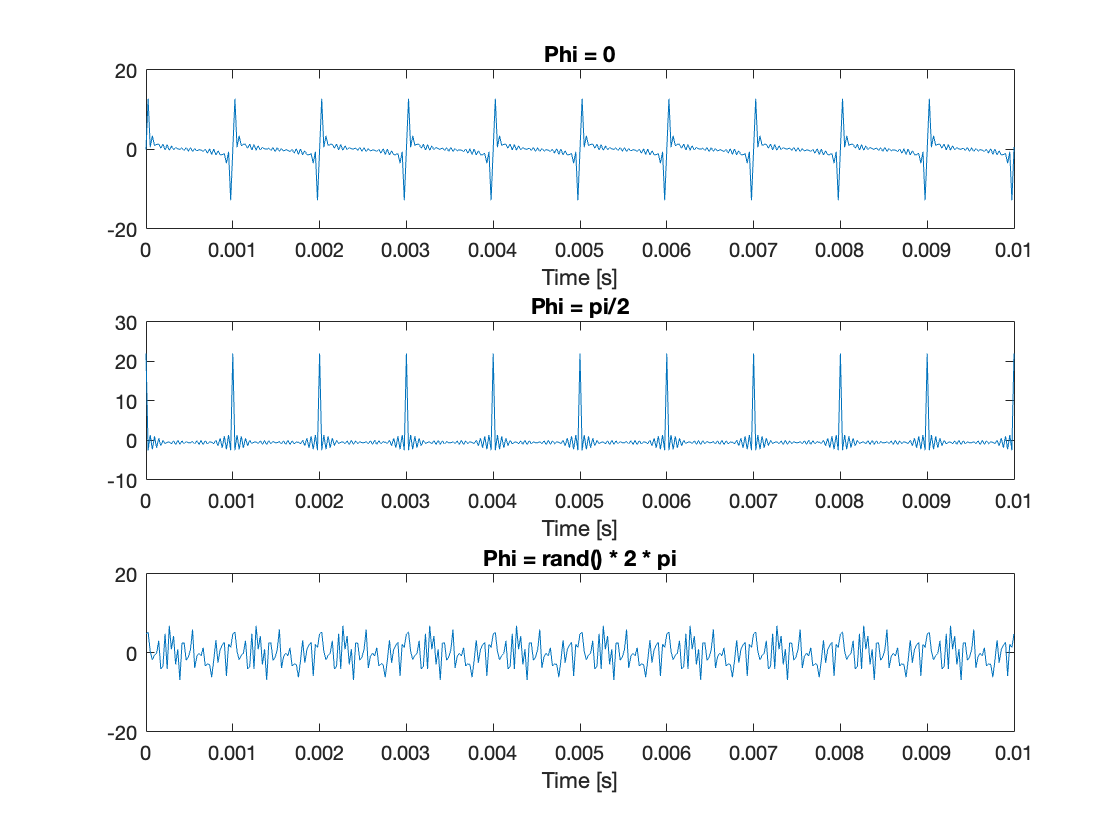

% Parameters for tone complex with zero phase:
A = 1;
f0 = 1000;
T = 5;
phi = 0;
N = 22;
fs = 41000;

% Genereate tone complex:
[sZero, timeVector] = generateToneComplex(A, f0, T, phi, fs, N);

% Save the tone complex to a .wav file:
audiowrite('ToneComplexZeroPhase.wav', sZero, fs, 'BitsPerSample', 32);

% Plot:
hold on
subplot(3, 1, 1)
plot(timeVector, sZero)
xlim([0, 0.01])
ylim([-20, 20])
title('Phi = 0')
xlabel('Time [s]')
hold off

% Parameters for tone complex with phase of pi/2:
A = 1;
f0 = 1000;
T = 5;
phi = pi/2;
N = 22;
fs = 41000;

% Generate tone complex with phase of pi/2:
[sPiOverTwo, timeVector] = generateToneComplex(A, f0, T, phi, fs, N);

% Save the tone complex to a .wav file:
audiowrite('ToneComplexPiOverTwoPhase.wav', sPiOverTwo, fs, 'BitsPerSample', 32);

% Plot:
hold on
subplot(3, 1, 2)
plot(timeVector, sPiOverTwo)
xlim([0, 0.01])
ylim([-10, 30])
title('Phi = pi/2')
xlabel('Time [s]')
hold off

% Parameters for tone complex with phase of pi/2:
A = 1;
f0 = 1000;
T = 5;
phi = 'random';
N = 22;
fs = 41000;

% Generate tone complex with phase of pi/2:
[sRandom, timeVector] = generateToneComplex(A, f0, T, phi, fs, N);

% Save the tone complex to a .wav file:
audiowrite('ToneComplexRandomPhase.wav', sRandom, fs, 'BitsPerSample', 32);

% Plot:
hold on
subplot(3, 1, 3)
plot(timeVector, sRandom)
xlim([0, 0.01])
ylim([-20, 20])
title('Phi = rand() * 2 * pi')
xlabel('Time [s]')
hold off

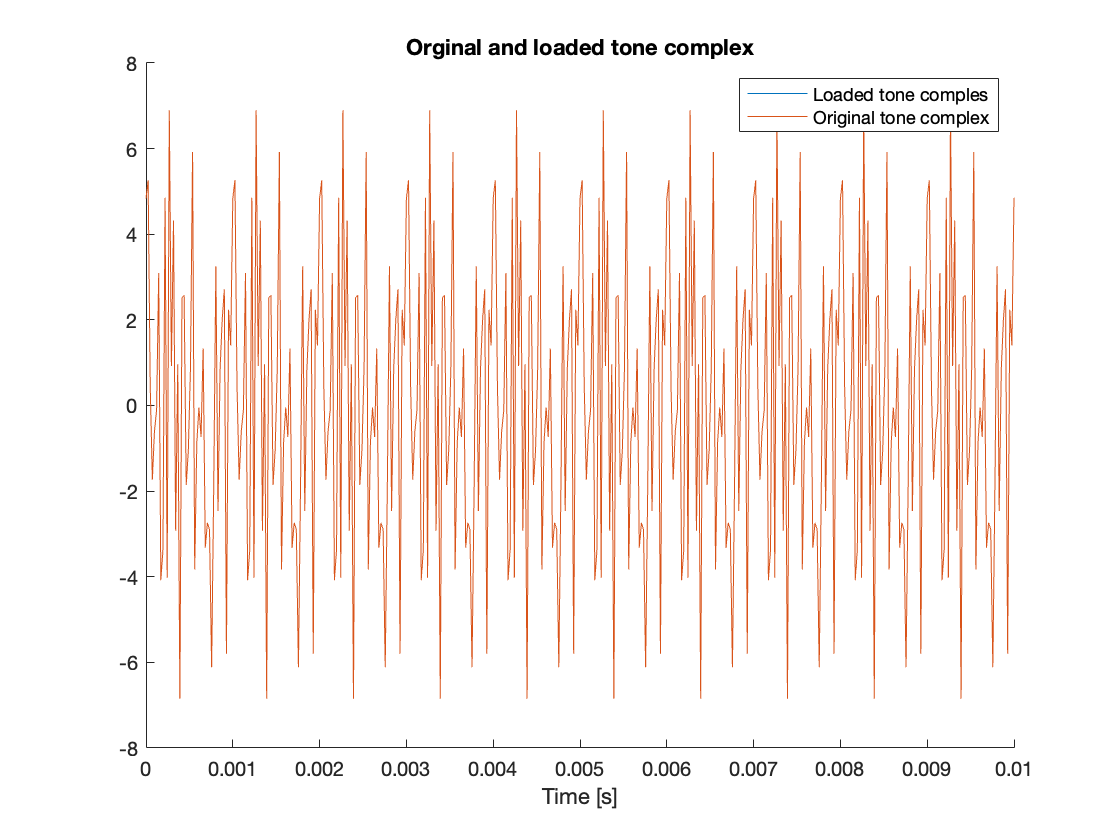


% Read the data:
[toneComplexZeroPhase, fs] = audioread('ToneComplexZeroPhase.wav');
toneComplexPiOverTwoPhase = audioread('ToneComplexPiOverTwoPhase.wav');
toneComplexRandomPhase = audioread('ToneComplexRandomPhase.wav');

timeVector = 0 : 1/fs : length(toneComplexZeroPhase) * 1/fs - 1/fs;

% Plot:
figure()
hold on
plot(timeVector, toneComplexRandomPhase)
plot(timeVector, sRandom)
xlim([0, 0.01])
title('Orginal and loaded tone complex')
legend('Loaded tone comples', 'Original tone complex')
xlabel('Time [s]')
hold off

function [s, timeVector] = generateToneComplex(A, f0, T, phi, fs, N)

timeVector = 0:1/fs:T-1/fs;

s = zeros(1, fs*T);

if phi == 'random'
    phi = rand([1, N])*2*pi;
    for k = 1:N
        s = s + A * sin(2 * pi * k * f0 * timeVector + phi(k));
    end
    
else
    for k = 1:N
        s = s + A * sin(2 * pi * k * f0 * timeVector + phi);
    end
end
end